# Config Settings

clear;
clc;
close all;

%Atmosphere settings
g = 9.81; % m/s^2
R = 287; % m^2/(s^2-K)
h = 250; % m layer height

%Launch Site Info
P_launch = 101325; % Pa
T_launch = 288.16; % K
rho_launch = 1.225; % kg/m^3
launch_site_asl = 0; % m

%Rocket Parameters
apogee = 10e3; %m
rocket_dry_mass = 39.61; %kg

%Drogue Chute Parameters
Cd_drogue = 1.55; % drogue parachute drag coefficient
diam_drogue = 0.9144; % drogue parachute diameter in [m]

%Main Chute Parameters
h_main = 300; % Main deployment altitude in meters
Cd_main = 2.2; % main parachute drag coefficient
diam_main = 3.048; % main parachute diameter in [m]


## Initialisation

%number of layers
n = apogee/h;

%initial position (apogee)
x0=0; % m
y0=0; % m
z0=apogee; % m

%initial velocity (at apogee)
vx0 = 0; % m/s
vy0 = 0; % m/s
vz0 = 0; % m/s

%get atmoshperic properties
atmos=atmospheric_model(apogee,launch_site_asl,T_launch,P_launch,rho_launch,R,g);
density = atmos(:,1);

%in the range of 165-230 degree in the early morning (avg 197.5)
%35-50 at noon @Cold lake mid August
wind_direction=(45)*ones(n,1);
curr_height = apogee;
counter=1;
x_total=0;
y_total=0;

%drogue: air resistance
%v=sqrt(2mg/density*C(coefficient)*Area)



## Main Loop

while(n>0)
    avg_rho = (1/2)*(density(ceil(curr_height)+1) + density(floor(curr_height-h)+1));
    if (curr_height > h_main)
        %t_layer: time it takes to travel through the current layer
        v_terminal_drogue = sqrt(8*rocket_dry_mass*g/(avg_rho*Cd_drogue*pi*diam_drogue^2));
        t_layer=h/v_terminal_drogue;
    else%curr_height < h_main
        v_terminal_main = sqrt(8*rocket_dry_mass*g/(avg_rho*Cd_main*pi*diam_main^2));
        t_layer=h/v_terminal_main;
    end
    %update the current height to one layer down
    curr_height=curr_height - h;
    wind_profile = magnitude_calculator(curr_height); %for checking function output
    wind_xcomponent=magnitude_calculator(curr_height)*sind(wind_direction(counter));
    wind_ycomponent=magnitude_calculator(curr_height)*cosd(wind_direction(counter));
    position_x = t_layer*wind_xcomponent; %distance by wind
    position_y = t_layer*wind_ycomponent;
    x_total=x_total+position_x;
    y_total=y_total+position_y;
    counter = counter + 1;
    n=n-1;
end
xposition_final=x0+x_total; %final x coordinate
yposition_final=y0+y_total; %final y coordinate
fprintf("x_coord: %.1f m\n",mean(xposition_final));

x_coord: 3146.1 m


fprintf("y_coord: %.1f m\n",mean(yposition_final));

y_coord: 3148.2 m


fprintf("Straight Line Distance From Apogee: %.1f m\n",sqrt(mean(xposition_final)^2 + mean(yposition_final)^2))

Straight Line Distance From Apogee: 4450.8 m


fprintf("Landing Velocity:%.2f m/s",sqrt(8*rocket_dry_mass*g/(rho_launch*Cd_main*pi*diam_main^2)));

Landing Velocity:6.29 m/s

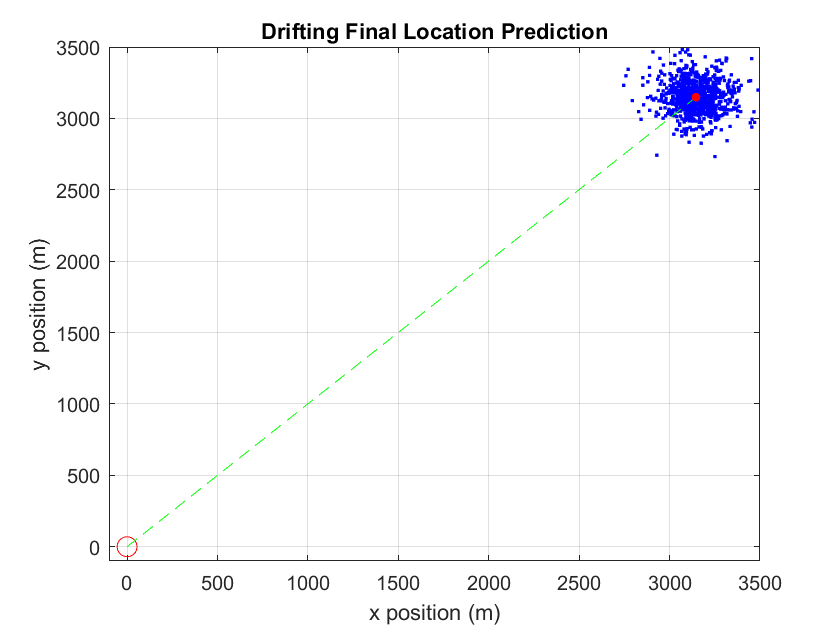


figure(1)
plot(xposition_final,yposition_final,"b.", "MarkerSize",5) 
hold on
plot(x0,y0,'ro',"MarkerSize",10)
plot([x0,mean(xposition_final)],[y0,mean(yposition_final)],'--g')
plot(mean(xposition_final),mean(yposition_final),"r.", "MarkerSize",15)
hold off
grid on
axis([-100 3500 -100 3500])
xlabel('x position (m)')
ylabel('y position (m)')
title('Drifting Final Location Prediction')

## Function Definitions

function vn = magnitude_calculator(x)
    varn = 1:0.01:10;  % Variance
    a = 37.55331224;
    b = 14.30107053;
    c = 6.7123204;
    v = a*exp((-(x/1000-b)^2) / (2*(c^2)));
    vn = v + sqrt(varn).*randn(size(varn)); % Signal + Noise
end

function atmos = atmospheric_model(apogee,launch_altitude,T_launch,P_launch,Rho_launch,R,g)
    %% Atmospheric Layer Settings
    Layer_Settings = [11000,-6.5e-3, 1; %end of layer in m (geometric altitude), layer coefficient in K/m, layer type 0=isothermal/1=gradient
                      25000, NaN, 0; 
                      47000, 3e-3, 1; 
                      53000, NaN, 0; 
                      79000, -4.5e-3, 1; 
                      90000, NaN, 0; 
                      105000, 4e-3, 1];
    %generate list of [density, pressure, temperature values] every meter
    %from h0 = launch altitude to hf = launch altitude + apogee
    %indexed such that atmos(i,:) -> atmos. properties at launch_altitude +
    %(i-1) (all altitudes in m)
    
    %preallocate memory
    atmos = zeros(ceil(apogee)+1,3); %[rho(agl+1),p(agl+1),T(agl+1)]
    
    %start loop
    geom_altitude = launch_altitude; %geometric altitude
    agl = 0; %altitude above launch altitude
    current_layer = find(geom_altitude<Layer_Settings(:,1));
    current_layer = current_layer(1);
    atmos(agl+1,:) = [Rho_launch,P_launch,T_launch];
    for agl=1:ceil(apogee)
        a = Layer_Settings(current_layer,2);
        if Layer_Settings(current_layer,3) == 0 % isothermal layer
            T = atmos(agl-1+1,3);
            P = atmos(agl-1+1,2) * exp(-g/(R*T)*1);
            rho = atmos(agl-1+1,1) * exp(-g/(R*T)*1);
        elseif Layer_Settings(current_layer,3) == 1 % gradient layer
            T = atmos(agl-1+1,3) + a*1;
            P = atmos(agl-1+1,2) * (T/atmos(agl-1+1,3))^(-g/(a*R));
            rho = atmos(agl-1+1,1) * (T/atmos(agl-1+1,3))^(-g/(a*R)-1);
        end
        atmos(agl+1,:) = [rho,P,T];
        geom_altitude = launch_altitude + agl;
        current_layer = find(geom_altitude<Layer_Settings(:,1));
        current_layer = current_layer(1);
    end
end